#### Test Case 1: 13 Cambridge Communities - Trapezoidal with dt = 0.05

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.05;

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X, trapNewtonLastIter] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    trapState(:,i) = convertSeirCellToMat(X(:,i));
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter', '-append');

f =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


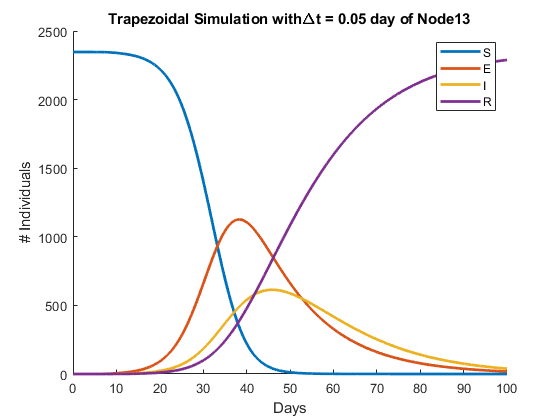

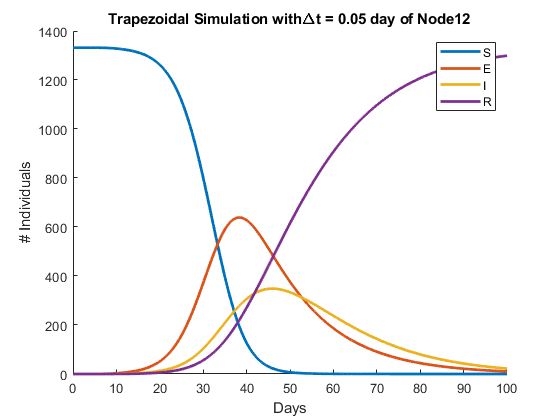

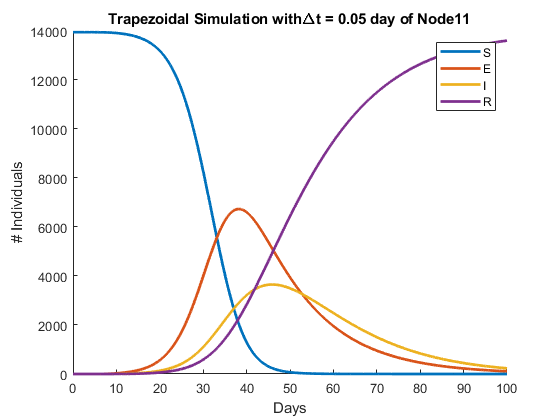

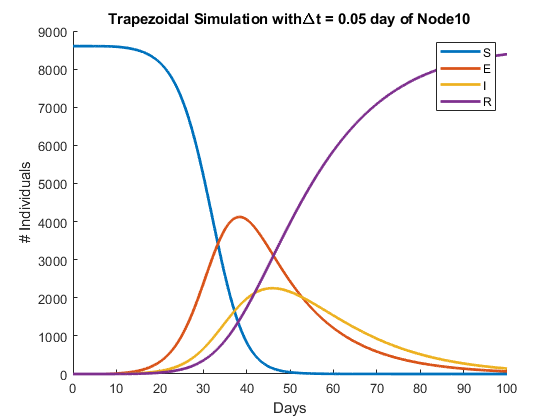

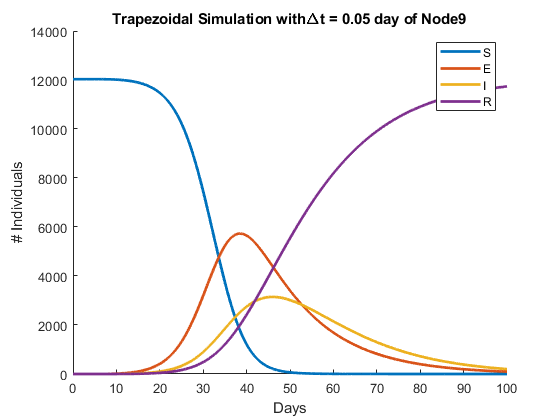

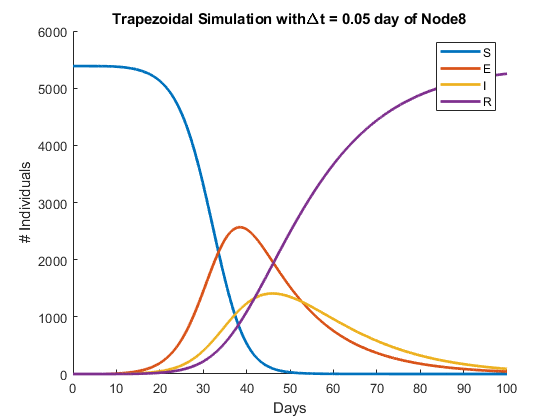

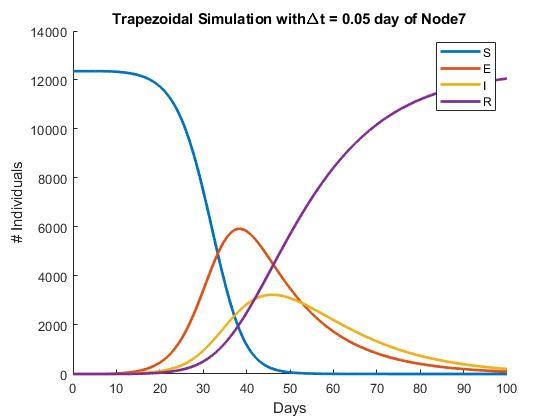

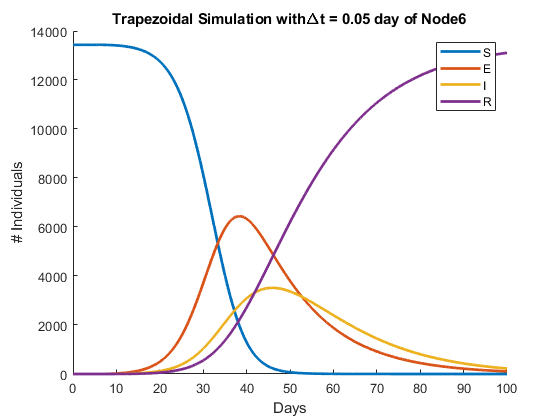

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep_desc = "\Deltat = 0.05 day";

load('Technical-Challenge/techChallengeStats.mat');
matState = trapState;
model_type = 'Trapezoidal';
seir_ylabel = '# Individuals';

plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);

#### Test Case 2: 13 Cambridge Communities - Forward Euler

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 1;

%select input evaluation function
eval_u = 'GenInputVec';

%select model evaluation function
eval_f = 'EVALF';

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
feElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    feState(:,i) = convertSeirCellToMat(X(:,i)); 
end

matState = feState;
model_type = 'Forward Euler';
timestep_desc = strcat("\Deltat = ", num2str(timestep), " day");
seir_ylabel = '# Individuals';

% plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);

save('Technical-Challenge/techChallengeStats.mat', 'feState', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');

#### Error Plot between Test Case 1 and 2  (Reference Trapezoidal VS Forward Euler)

clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

expDtType = "fixed";
refTimestep = 0.05;
expTimestep = 1;
expModelType = ' Forward Euler with \Deltat = 0.05 day';

refState = trapState;
expState = feState;

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

% plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
%     percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);

[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Test Case 3: 13 Cambridge Communities - Adaptive Trapezoidal

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.05;

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X, trapAdaptiveT, trapAdaptiveNewtonLastIter] = trapezoidalAdaptive(P, x_start, p, u, t_stop, timestep); %t_start is always 0
trapAdaptiveElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    trapAdaptiveState(:,i) = convertSeirCellToMat(X(:,i));
end

save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveState', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveElapsedTime', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveT', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveNewtonLastIter', '-append');

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep_desc = ' Adaptive Time Steps';

load('Technical-Challenge/techChallengeStats.mat');
matState = trapAdaptiveState;
model_type = 'Trapezoidal';
seir_ylabel = '# Individuals';

plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);

#### Error Plot between Test Case 1 and 3 (Reference Trapezoidal VS Adaptive Trapezoidal)

f =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


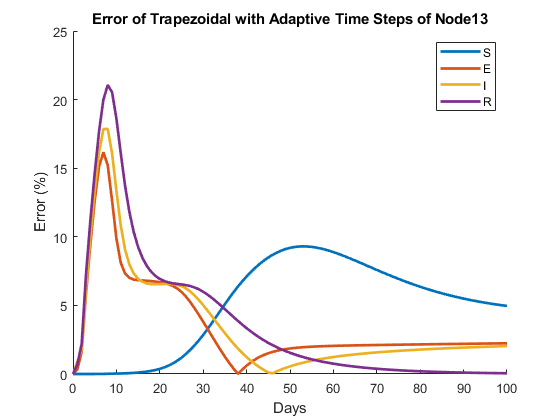

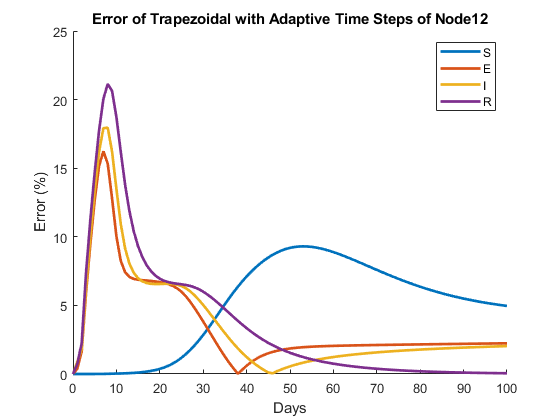

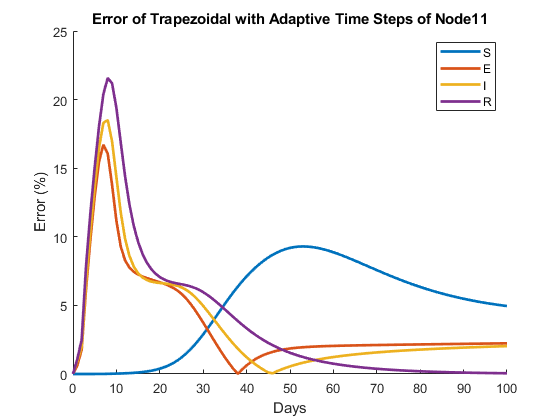

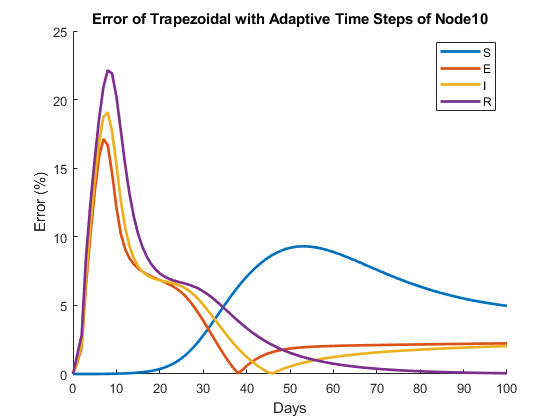

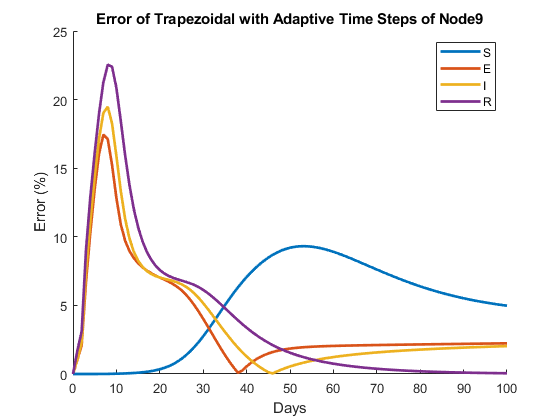

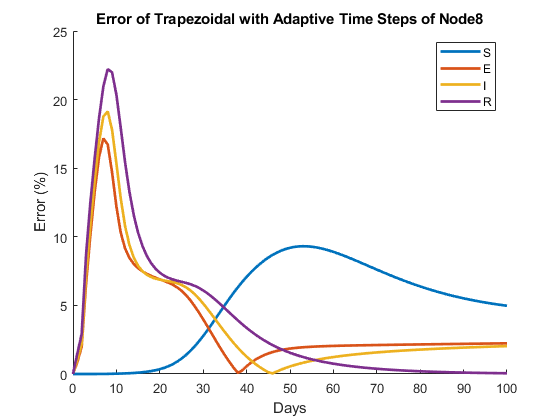

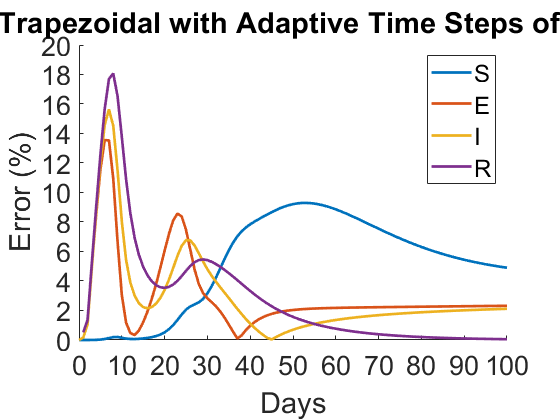

f =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


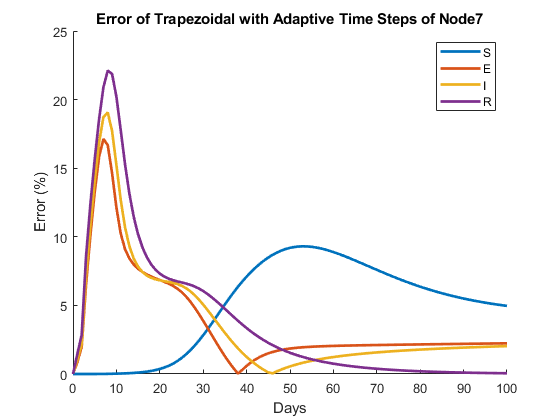

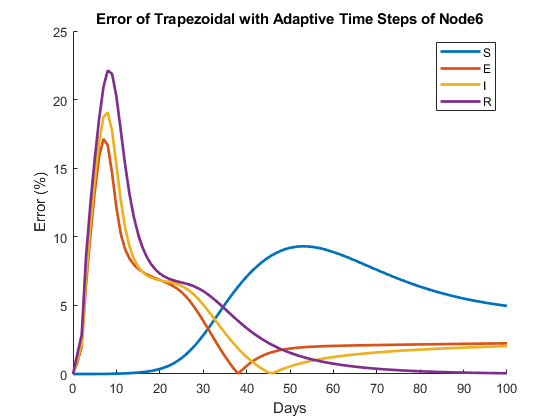

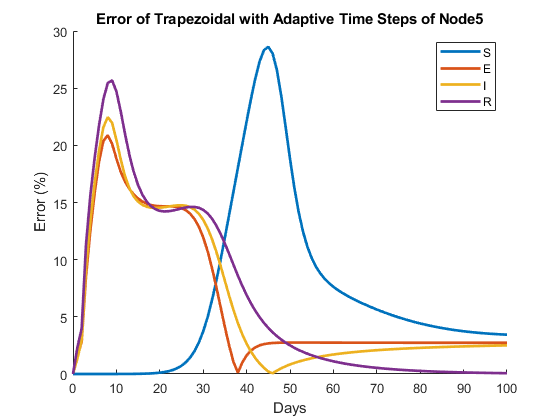

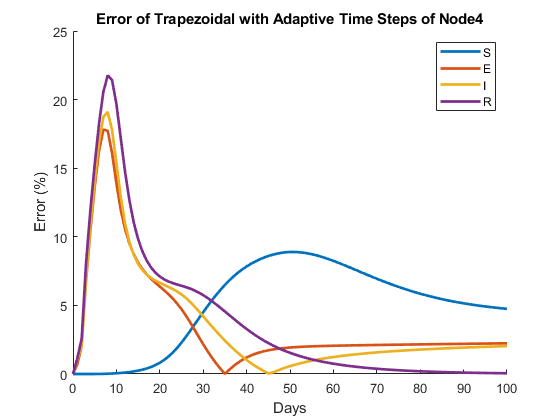

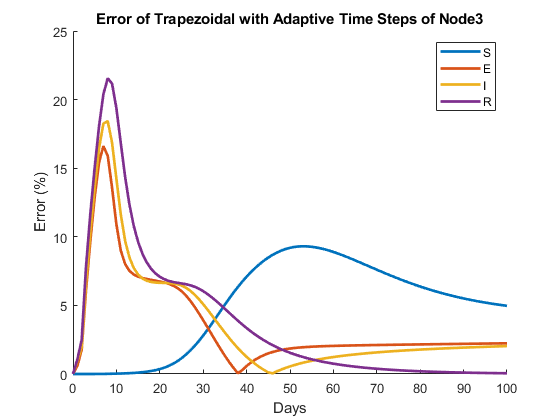

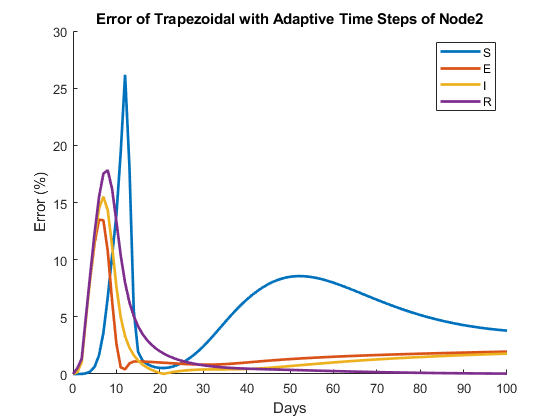

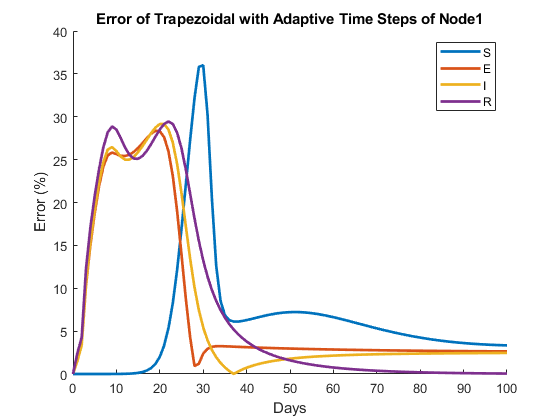

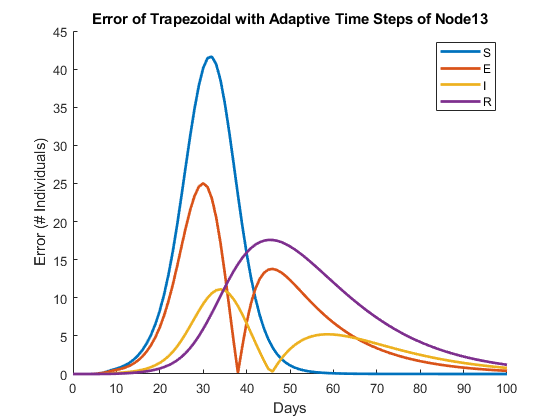

clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

expDtType = "adaptive";
refTimestep = 0.05;
expTimestep = trapAdaptiveT;
expModelType = ' Trapezoidal with Adaptive Time Steps';

refState = trapState;
expState = trapAdaptiveState;

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
    percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);


[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Test Case 4: 13 Cambridge Communities - Trapezoidal with dt = 0.1

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.1;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt01] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0

Step = 10/1000
Step = 20/1000
Step = 30/1000


trapElapsedTime_dt01 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)    
    trapState_dt01(:,i) = convertSeirCellToMat(X(:,i));    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt01', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt01', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt01', '-append');

#### Test Case 5: 13 Cambridge Communities - Trapezoidal with dt = 0.2

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.2;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt02] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0

Step = 10/500
Step = 20/500
Step = 30/500
Step = 40/500
Step = 50/500
Step = 60/500
Step = 70/500
Step = 80/500
Step = 90/500
Step = 100/500
Step = 110/500
Step = 120/500
Step = 130/500
Step = 140/500
Step = 150/500
Step = 160/500
Step = 170/500
Step = 180/500
Step = 190/500
Step = 200/500
Step = 210/500
Step = 220/500
Step = 230/500
Step = 240/500
Step = 250/500
Step = 260/500
Step = 270/500
Step = 280/500
Step = 290/500
Step = 300/500
Step = 310/500
Step = 320/500
Step = 330/500
Step = 340/500
Step = 350/500
Step = 360/500
Step = 370/500
Step = 380/500
Step = 390/500
Step = 400/500
Step = 410/500
Step = 420/500
Step = 430/500
Step = 440/500
Step = 450/500
Step = 460/500
Step = 470/500
Step = 480/500
Step = 490/500
Step = 500/500


trapElapsedTime_dt02 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)  
    trapState_dt02(:,i) = convertSeirCellToMat(X(:,i));  
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt02', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt02', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt02', '-append');

#### Test Case 6: 13 Cambridge Communities - Trapezoidal with dt = 0.5

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.5;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt05] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0

Step = 10/200
Step = 20/200
Step = 30/200
Step = 40/200
Step = 50/200
Step = 60/200
Step = 70/200
Step = 80/200
Step = 90/200
Step = 100/200
Step = 110/200
Step = 120/200
Step = 130/200
Step = 140/200
Step = 150/200
Step = 160/200
Step = 170/200
Step = 180/200
Step = 190/200
Step = 200/200


trapElapsedTime_dt05 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapState_dt05(:,i) = convertSeirCellToMat(X(:,i));
    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt05', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt05', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt05', '-append');

#### Test Case 7: 13 Cambridge Communities - Trapezoidal with dt = 1

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 1;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt1] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0

Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100


trapElapsedTime_dt1 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapState_dt1(:,i) = convertSeirCellToMat(X(:,i));
    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt1', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt1', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt1', '-append');

#### Error Plot between Test Case 1 and 4, 5, 6, 7 with Trap fixed time step

f =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


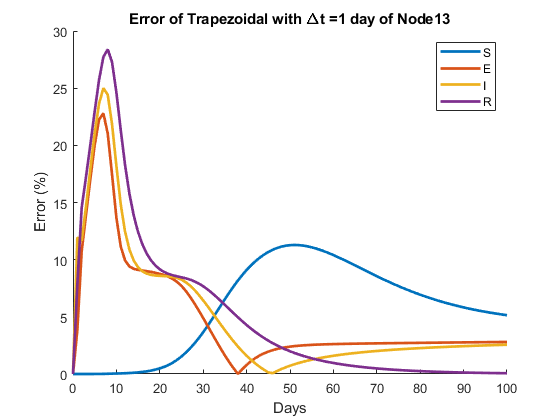

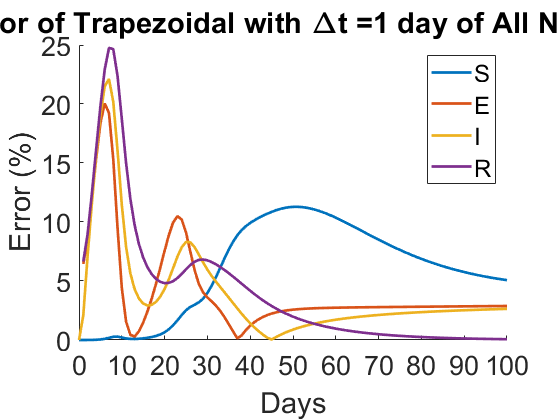

f =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


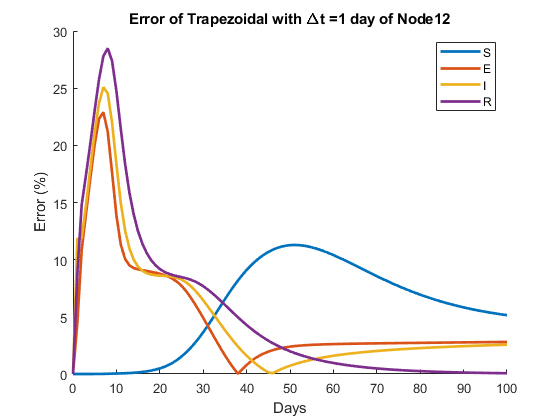

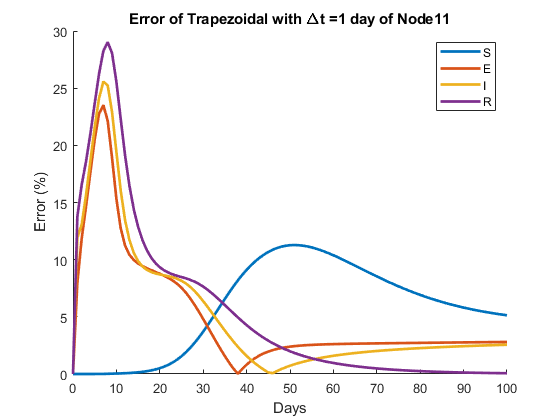

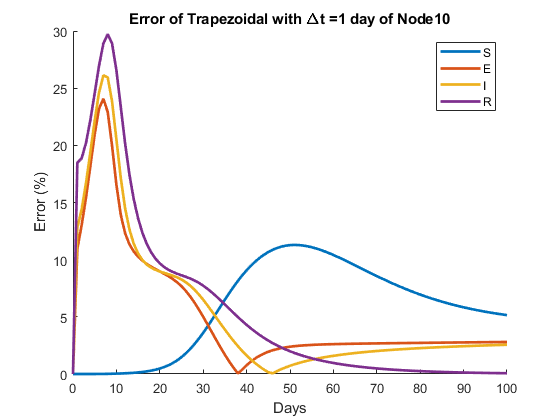

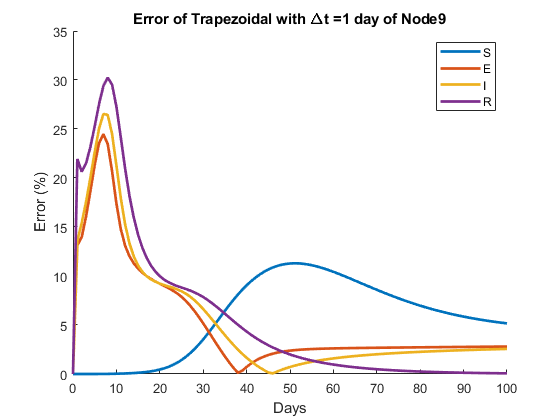

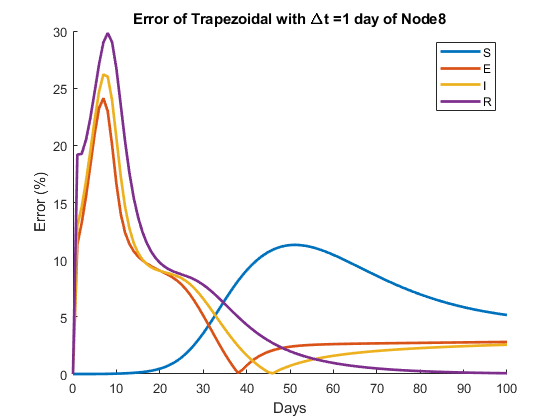

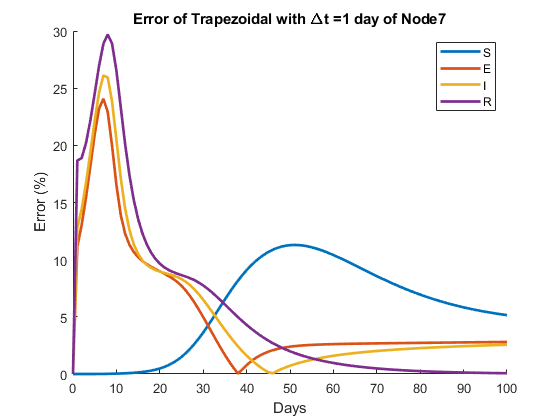

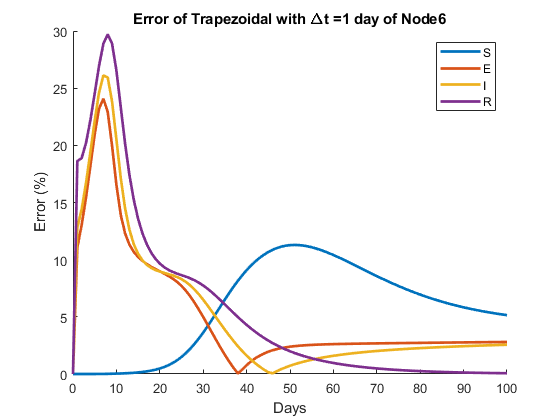

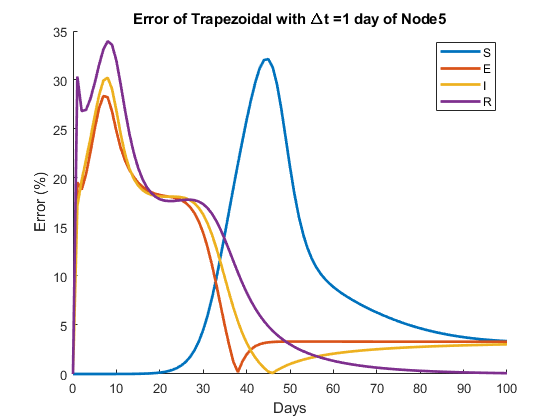

clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

expDtType = "fixed";
refTimestep = 0.05;
expTimestep = 1;
expModelType = strcat(' Trapezoidal with \Deltat = ', num2str(expTimestep), ' day');

refState = trapState;
expState = trapState_dt1;

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
    percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);


[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Rerun Simulations Several Times to Measure Elapsed Times

clc; clear; close all;

numSimulation = 5;

t_start = 0;
t_stop = 100;

timestep = 1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt1] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt1(i) = toc;
end

Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100
Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100
Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100
Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100
Step = 10/100
Step = 20/100
Step = 30/100
Step = 40/100
Step = 50/100
Step = 60/100
Step = 70/100
Step = 80/100
Step = 90/100
Step = 100/100


trapElapsedTime_dt1 = sort(trapElapsedTime_dt1);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt1', '-append');

timestep = 0.5;
[P, x_start, p, u] = initializeCambridgeCommunities();  
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt05] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt05(i) = toc;
end

Step = 10/200
Step = 20/200
Step = 30/200
Step = 40/200
Step = 50/200
Step = 60/200
Step = 70/200
Step = 80/200
Step = 90/200
Step = 100/200
Step = 110/200
Step = 120/200
Step = 130/200
Step = 140/200
Step = 150/200
Step = 160/200
Step = 170/200
Step = 180/200
Step = 190/200
Step = 200/200
Step = 10/200
Step = 20/200
Step = 30/200
Step = 40/200
Step = 50/200
Step = 60/200
Step = 70/200
Step = 80/200
Step = 90/200
Step = 100/200
Step = 110/200
Step = 120/200
Step = 130/200
Step = 140/200
Step = 150/200
Step = 160/200
Step = 170/200
Step = 180/200
Step = 190/200
Step = 200/200
Step = 10/200
Step = 20/200
Step = 30/200
Step = 40/200
Step = 50/200
Step = 60/200
Step = 70/200
Step = 80/200
Step = 90/200
Step = 100/200
Step = 110/200
Step = 120/200
Step = 130/200
Step = 140/200
Step = 150/200
Step = 160/200
Step = 170/200
Step = 180/200
Step = 190/200
Step = 200/200
Step = 10/200
Step = 20/200
Step = 30/200
Step = 40/200
Step = 50/200
Step = 60/200
Step = 70/200
Step = 80/200
Step = 90/200
S

trapElapsedTime_dt05 = sort(trapElapsedTime_dt05);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt05', '-append');

timestep = 0.2;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt02] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt02(i) = toc;
end

Step = 10/500
Step = 20/500
Step = 30/500
Step = 40/500
Step = 50/500
Step = 60/500
Step = 70/500
Step = 80/500
Step = 90/500
Step = 100/500
Step = 110/500
Step = 120/500
Step = 130/500
Step = 140/500
Step = 150/500
Step = 160/500
Step = 170/500
Step = 180/500
Step = 190/500
Step = 200/500
Step = 210/500
Step = 220/500
Step = 230/500
Step = 240/500
Step = 250/500
Step = 260/500
Step = 270/500
Step = 280/500
Step = 290/500
Step = 300/500
Step = 310/500
Step = 320/500
Step = 330/500
Step = 340/500
Step = 350/500
Step = 360/500
Step = 370/500
Step = 380/500
Step = 390/500
Step = 400/500
Step = 410/500
Step = 420/500
Step = 430/500
Step = 440/500
Step = 450/500
Step = 460/500
Step = 470/500
Step = 480/500
Step = 490/500
Step = 500/500
Step = 10/500
Step = 20/500
Step = 30/500
Step = 40/500
Step = 50/500
Step = 60/500
Step = 70/500
Step = 80/500
Step = 90/500
Step = 100/500
Step = 110/500
Step = 120/500
Step = 130/500
Step = 140/500
Step = 150/500
Step = 160/500
Step = 170/500
Step = 180/50

trapElapsedTime_dt02 = sort(trapElapsedTime_dt02);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt02', '-append');

timestep = 0.1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt01] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt01(i) = toc;
end

Step = 10/1000
Step = 20/1000
Step = 30/1000
Step = 40/1000
Step = 50/1000
Step = 60/1000
Step = 70/1000
Step = 80/1000
Step = 90/1000
Step = 100/1000
Step = 110/1000
Step = 120/1000
Step = 130/1000
Step = 140/1000
Step = 150/1000
Step = 160/1000
Step = 170/1000
Step = 180/1000
Step = 190/1000
Step = 200/1000
Step = 210/1000
Step = 220/1000
Step = 230/1000
Step = 240/1000
Step = 250/1000
Step = 260/1000
Step = 270/1000
Step = 280/1000
Step = 290/1000
Step = 300/1000
Step = 310/1000
Step = 320/1000
Step = 330/1000
Step = 340/1000
Step = 350/1000
Step = 360/1000
Step = 370/1000
Step = 380/1000
Step = 390/1000
Step = 400/1000
Step = 410/1000
Step = 420/1000
Step = 430/1000
Step = 440/1000
Step = 450/1000
Step = 460/1000
Step = 470/1000
Step = 480/1000
Step = 490/1000
Step = 500/1000
Step = 510/1000
Step = 520/1000
Step = 530/1000
Step = 540/1000
Step = 550/1000
Step = 560/1000
Step = 570/1000
Step = 580/1000
Step = 590/1000
Step = 600/1000
Step = 610/1000
Step = 620/1000
Step = 630/1000
S

trapElapsedTime_dt01 = sort(trapElapsedTime_dt01);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt01', '-append');

timestep = 0.05;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime(i) = toc;
end

Step = 10/2000
Step = 20/2000
Step = 30/2000
Step = 40/2000
Step = 50/2000
Step = 60/2000
Step = 70/2000
Step = 80/2000
Step = 90/2000
Step = 100/2000
Step = 110/2000
Step = 120/2000
Step = 130/2000
Step = 140/2000
Step = 150/2000
Step = 160/2000
Step = 170/2000
Step = 180/2000
Step = 190/2000
Step = 200/2000
Step = 210/2000
Step = 220/2000
Step = 230/2000
Step = 240/2000
Step = 250/2000
Step = 260/2000
Step = 270/2000
Step = 280/2000
Step = 290/2000
Step = 300/2000
Step = 310/2000
Step = 320/2000
Step = 330/2000
Step = 340/2000
Step = 350/2000
Step = 360/2000
Step = 370/2000
Step = 380/2000
Step = 390/2000
Step = 400/2000
Step = 410/2000
Step = 420/2000
Step = 430/2000
Step = 440/2000
Step = 450/2000
Step = 460/2000
Step = 470/2000
Step = 480/2000
Step = 490/2000
Step = 500/2000
Step = 510/2000
Step = 520/2000
Step = 530/2000
Step = 540/2000
Step = 550/2000
Step = 560/2000
Step = 570/2000
Step = 580/2000
Step = 590/2000
Step = 600/2000
Step = 610/2000
Step = 620/2000
Step = 630/2000
S

trapElapsedTime = sort(trapElapsedTime);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime', '-append');

clc; clear; close all;

numSimulation = 5;

t_start = 0;
t_stop = 100;
timestep = 1;

eval_u = 'GenInputVec';
eval_f = 'EVALF';

timestep = 1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt1(i) = toc;
end
feElapsedTime_dt1 = sort(feElapsedTime_dt1);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt1', '-append');

timestep = 0.5;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt05(i) = toc;
end
feElapsedTime_dt05 = sort(feElapsedTime_dt05);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt05', '-append');


timestep = 0.2;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt02(i) = toc;
end
feElapsedTime_dt02 = sort(feElapsedTime_dt02);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt02', '-append');

timestep = 0.1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt01(i) = toc;
end
feElapsedTime_dt01 = sort(feElapsedTime_dt01);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt01', '-append');

timestep = 0.05;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime(i) = toc;
end
feElapsedTime = sort(feElapsedTime);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');